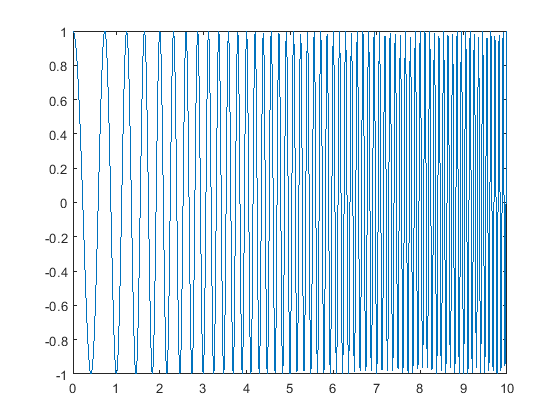

clear all;
dt = 0.01;
t = 0 : dt : 10;
N = length(t);
gain1 = 1;
gain2 = 1;
startf1 = 1;
startf2 = 1;
time1 = 1;
time2 = 1;
changef1 = 2;
changef2 = 2;
number = 0;
noiseSD = 1;

% chirp signal
y1 = gain1 * chirp(t, startf1, time1, changef1); 
y2 = gain2 * chirp(t, startf2, time2, changef2);

plot(t,y1)

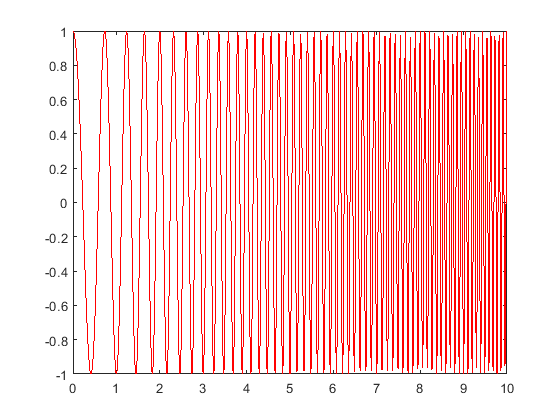

plot(t,y2,'r')

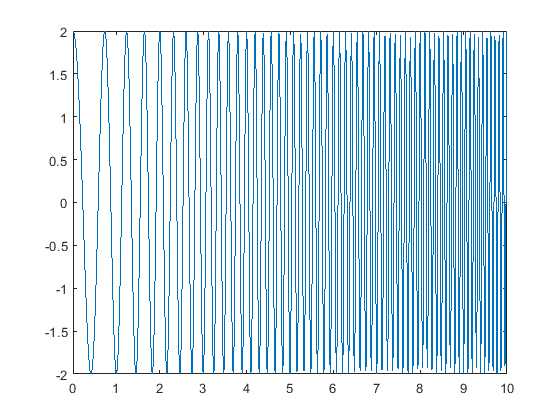

plot(t,y1+y2)

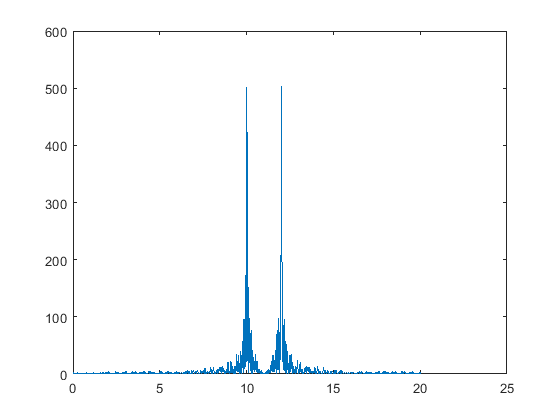

r1 = [ zeros(1,N), y1, zeros(1,N) ];
r2 = [ zeros(1,N+200), y2, zeros(1,N-200) ];
            
r = (r1 + r2) + randn(1,length(r1 + r2))*number*noiseSD;    

% correlation
    ct1 = length(r)-N;
        for a = 0:ct1
            c(a+1) = r(a+1:a+N)*y1';
        end

        plot((0:length(c)-1)*dt,abs(c))

## rectangular

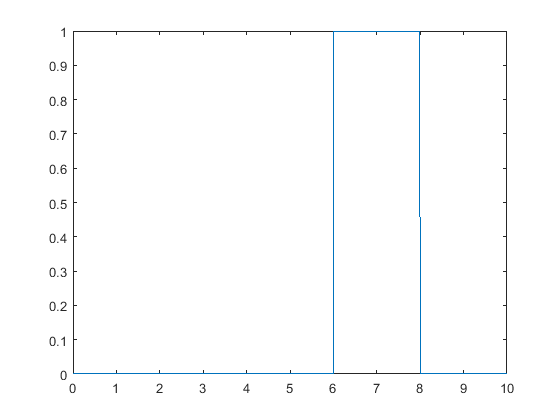

%rectangular

rect=zeros(1,length(t)); %length(c)
for i=1:length(t) %length(t)+N+1
    if t(i) > 6 && t(i) < 8
        rect(i) = 1; 
    end
end
plot((0:length(t)-1)*dt,rect)%(0:length(c)-1)*dt

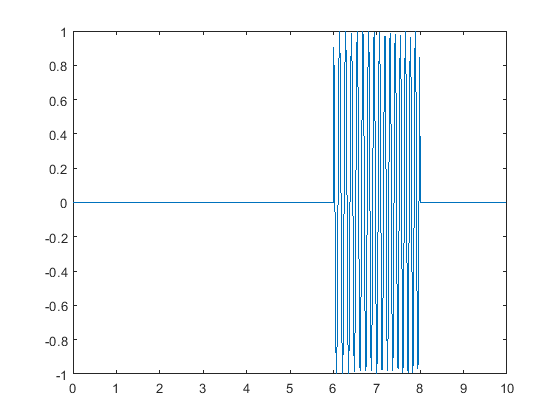


yt1 = y1.*rect;
yt2 = y2.*rect;
yt3 = (y1+y2).*rect;

plot((0:length(t)-1)*dt,(yt1)) %(0:length(c)-1)*dt

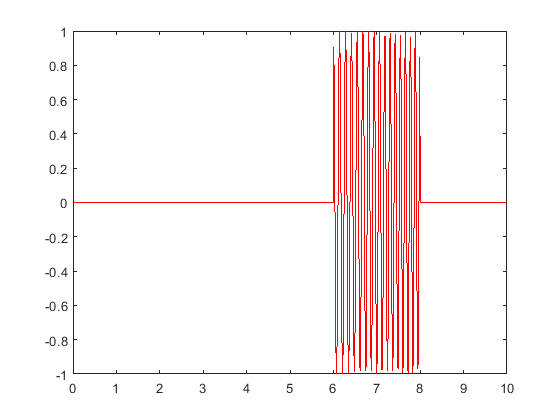

plot((0:length(t)-1)*dt,(yt2),'r')

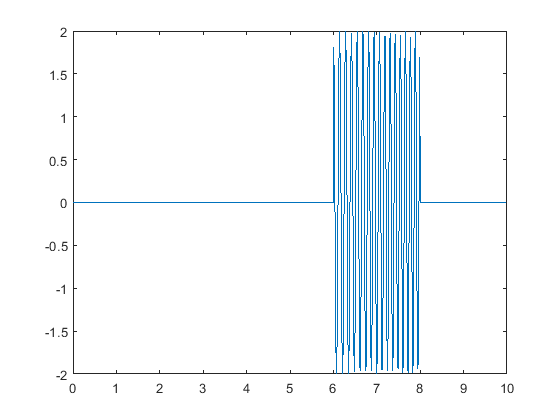

plot((0:length(t)-1)*dt,(yt3))


Xt1 = fft(yt1);
Xt2 = fft(yt2);
Xt3 = fft(yt3);

Xt = Xt1 .* Xt2

Xt = 	1.0e+03 *

   0.0010 + 0.0000i  -0.0006 - 0.0004i   0.0001 + 0.0002i   0.0000 - 0.0000i  -0.0004 + 0.0003i   0.0010 - 0.0001i  -0.0009 - 0.0005i   0.0002 + 0.0004i   0.0000 - 0.0000i  -0.0002 + 0.0002i   0.0010 - 0.0002i  -0.0012 - 0.0007i   0.0003 + 0.0008i   0.0001 - 0.0001i  -0.0000 + 0.0001i   0.0010 - 0.0003i  -0.0016 - 0.0008i   0.0005 + 0.0014i   0.0003 - 0.0004i   0.0000 + 0.0000i   0.0010 - 0.0004i  -0.0021 - 0.0010i   0.0007 + 0.0023i   0.0006 - 0.0008i   0.0001 - 0.0001i   0.0009 - 0.0006i  -0.0027 - 0.0013i   0.0009 + 0.0034i   0.0012 - 0.0014i  -0.0000 - 0.0002i   0.0009 - 0.0008i  -0.0036 - 0.0016i   0.0012 + 0.0051i   0.0022 - 0.0023i  -0.0003 - 0.0005i   0.0007 - 0.0011i  -0.0049 - 0.0020i   0.0016 + 0.0075i   0.0039 - 0.0037i  -0.0008 - 0.0011i   0.0005 - 0.0016i  -0.0068 - 0.0023i   0.0022 + 0.0112i   0.0067 - 0.0058i  -0.0017 - 0.0022i  -0.0001 - 0.0024i  -0.0099 - 0.0026i   0.0034 + 0.0173i   0.0118 - 0.0093i  -0.0036 - 0.0046i


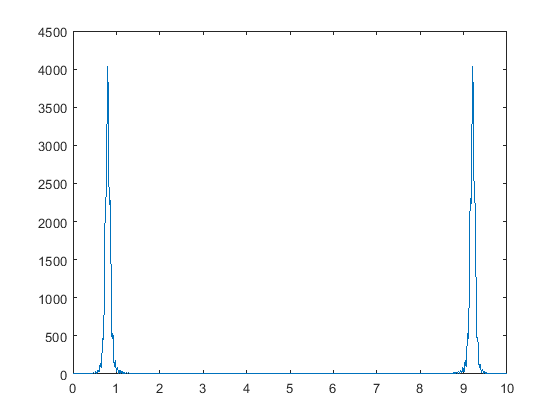

plot((0:length(t)-1)*dt,abs(Xt))


%plot((0:length(t)-1)*dt,abs(Xt3))
%iXt = ifft(Xt)
%plot((0:length(c)-1)*dt,abs(iXt))

## hanning

% hanning (0 <= n <= M - 1)
% 1/2 * (1 - cos(2*pi*n/(M-1)))


## hamming

% hamming
% 0.54 - 0.46 * cos(2*pi*n/(M-1))


## blackman

% blackman
% 0.42 - 0.5 * cos(2*pi*n/(M-1)) + 0.08 * cos(4*pi*n/(M-1))


## kaiser

% kaiser
% i0*[ (alpa * sqrt({(M-1)/2)}^2 - {n - (M-1)/2)}^2) ) ]...
% / i0*[(alpa * {(M-1)/2)}^2)]